close all;
clear all;
% define inputs and prepare for CBC
w0 = 2*pi;
target = 3;
x_init = [0, 0];
periods = 30;
dt = 1/1000;
[model, input, trial, control] = CL_model_reset(w0,target, x_init, periods, dt);
control.Kd = 10;
control.Kp = 100;

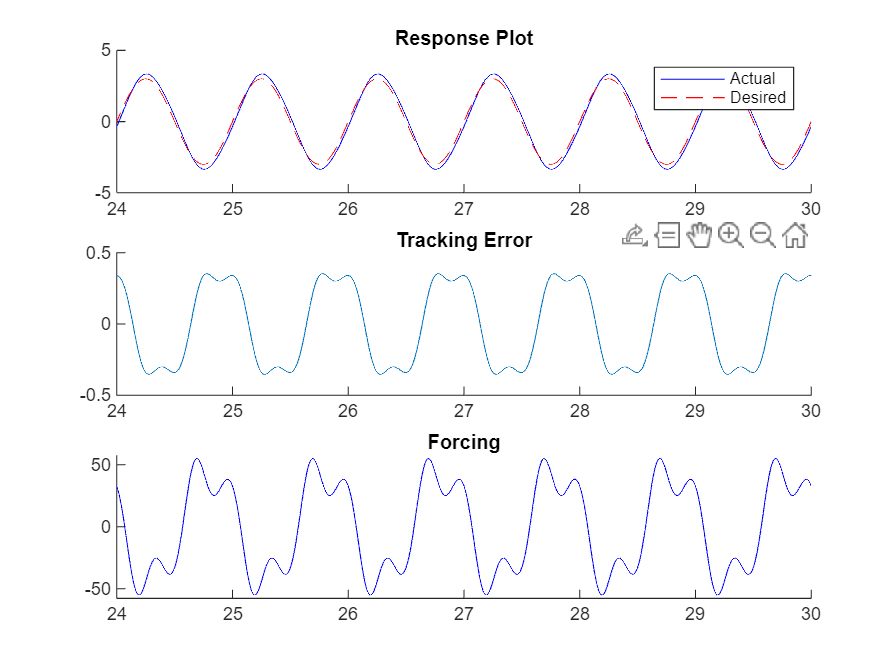

[input_out, trial_out] = closedloop_test(model, input, trial, control);
[f] = plot_CL_inner(input_out, trial_out, control);